# Plotting simple functions with MATLAB plot.m

One advantage of MATLAB is the ease with which a plot of several functions can be computed and overlaid.  A quick visual inspection of a problem often gives valuable engineering insight which guides the next steps. Hence, learn to plot things quickly as it will help with the engineering. This file gives some illustrations of simple uses of  the plot command which will be enough for most students to generate smart figures to use in reports.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Introduction

- Plotting with simple row vectors using plot.m

- Plotting with a large numbers of points

- Example of a smooth curve and labels

- Dealing with more complicated function relationships

- Overlaying plots of several curves using hold on

## 1. Introduction

A plot comprises a set of paired values, for example [x1,x2,x3,x4] and [y1,y2,y3,y4] so first we need to remind ourselves how MATLAB stores values and then show how these can be plotted.

### Row vector notation

A set of values can be defined using square brackets and spaces or commas to separate values. For example look at the following lines of code and modify these to see how they work.

x = [1 2 5 6]

x =      1     2     5     6


y = [-3 6 10 22 51]

y =     -3     6    10    22    51


z = [2,3,5,7,8,10,21,15,-1, 8 , 99]

z =      2     3     5     7     8    10    21    15    -1     8    99


#### NOTE: Everything below will also work identically with column vectors.

## 2. Plotting with simple row vectors using plot.m

In order to plot  [x1,x2,x3,x4,..] against [y1,y2,y3,y4,...] we mean plot the points (x1,y1), (x2,y2), (x3,y3) and so on.  MATLAB will do this if you supply the names of the vectors containing the values.  Be careful to make sure the vectors have exactly the same number of values or an error message will occur. 

Try changing the values in lines 6 and 7 below to create your own plot.

disp('BEGINNING OF SECTION 2');

BEGINNING OF SECTION 2


x=[1 2 4 6 10]

x =      1     2     4     6    10


y=[-1 3 5 2 -2]

y =     -1     3     5     2    -2


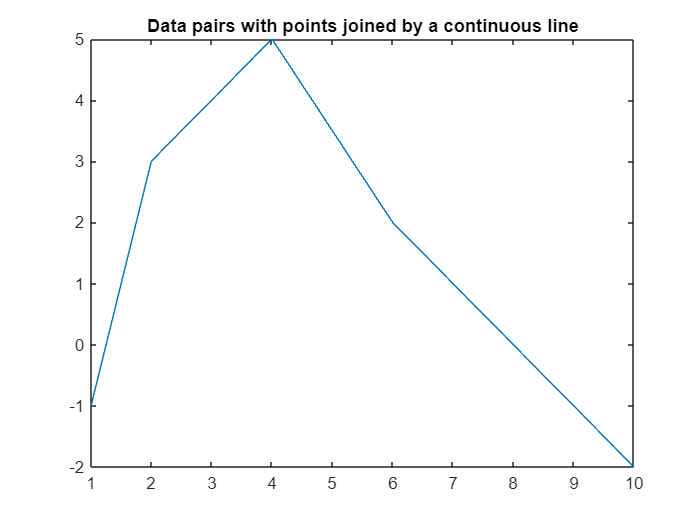

figure
plot(x,y)
title('Data pairs with points joined by a continuous line')

Note how MATLAB will, by default, join the points with a line, but you can avoid this if it is not helpful by specifying the option of line type, for example:

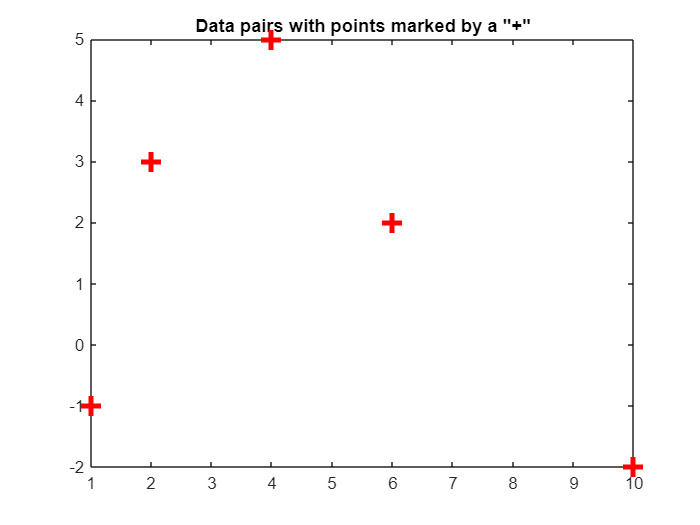

figure
plot(x,y,'r+','markersize',12,'linewidth',3)
title('Data pairs with points marked by a "+"')

## 3. Plotting with a large numbers of points

In general we may want to plot a large number of points and we do no want to have to enter these manually in the code. MATLAB can auto-generate suitable row vectors for you. The easiest way is probably with ***linspace.m*** which allows you to set a minimum, maximum and how many points you want in total. Look at the lines 16 and 17 and edit to ensure you understand what is happening.

disp('BELOW is SECTION 3')

BELOW is SECTION 3


x = linspace(-2,4,8)

x =    -2.0000   -1.1429   -0.2857    0.5714    1.4286    2.2857    3.1429    4.0000


y = linspace(2,8,12)

y =     2.0000    2.5455    3.0909    3.6364    4.1818    4.7273    5.2727    5.8182    6.3636    6.9091    7.4545    8.0000


Once you have decided the 'x' values, one can easily compute something like 'f(x)' automatically using suitable MATLAB commands, for example look at the code for the following:


$$f\left(x\right)=\sin \left(2x+3\right);\;\;g\left(y\right)={7\ldotp 1e}^{-0\ldotp 2y-1}$$


f = sin(2*x+3)

f =    -0.8415    0.6551    0.6541   -0.8422   -0.4133    0.9603    0.1386   -1.0000


g = 7.1*exp(-0.2*y-1)

g =     1.7508    1.5699    1.4076    1.2622    1.1317    1.0147    0.9099    0.8158    0.7315    0.6559    0.5881    0.5273


Now you are ready to plot exactly as in section 2 above:

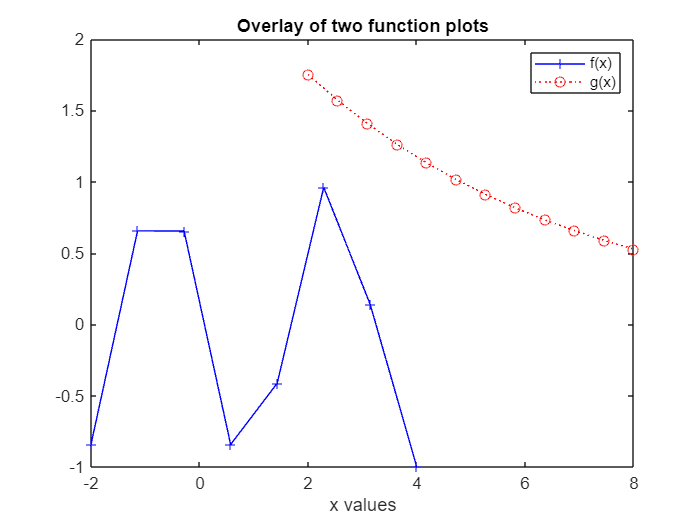

figure
plot(x,f,'b+-',y,g,'ro:')
legend('f(x)','g(x)')
title('Overlay of two function plots')
xlabel('x values')

Once you are happy with the above, try changing lines 14 and 15 to include 100s of points for a smoother curve and also the function definitions in 16 and 17.

## 4. Example of a smooth curve and labels

Now we show that smooth curves can be obtained by auto-generating a large number of values. We also add labels to the axes and a title for a more professional look. Consider the function:


$$f\left(x\right)=\sin \left(2x+3\right)+\;{7\ldotp 1e}^{-0\ldotp 2y-1}$$


disp('BELOW is SECTION 4')

BELOW is SECTION 4


x = linspace(0,8,200)

x =          0    0.0402    0.0804    0.1206    0.1608    0.2010    0.2412    0.2814    0.3216    0.3618    0.4020    0.4422    0.4824    0.5226    0.5628    0.6030    0.6432    0.6834    0.7236    0.7638    0.8040    0.8442    0.8844    0.9246    0.9648    1.0050    1.0452    1.0854    1.1256    1.1658    1.2060    1.2462    1.2864    1.3266    1.3668    1.4070    1.4472    1.4874    1.5276    1.5678    1.6080    1.6482    1.6884    1.7286    1.7688    1.8090    1.8492    1.8894    1.9296    1.9698


w = sin(2*x+3)+7.1*exp(-0.2*x-1)

w =     2.7531    2.6522    2.5511    2.4502    2.3502    2.2515    2.1547    2.0601    1.9684    1.8799    1.7951    1.7145    1.6384    1.5671    1.5011    1.4407    1.3860    1.3374    1.2950    1.2589    1.2294    1.2064    1.1901    1.1803    1.1771    1.1803    1.1898    1.2055    1.2271    1.2544    1.2871    1.3249    1.3673    1.4142    1.4649    1.5192    1.5765    1.6364    1.6984    1.7619    1.8266    1.8917    1.9570    2.0217    2.0854    2.1477    2.2079    2.2656    2.3204    2.3718


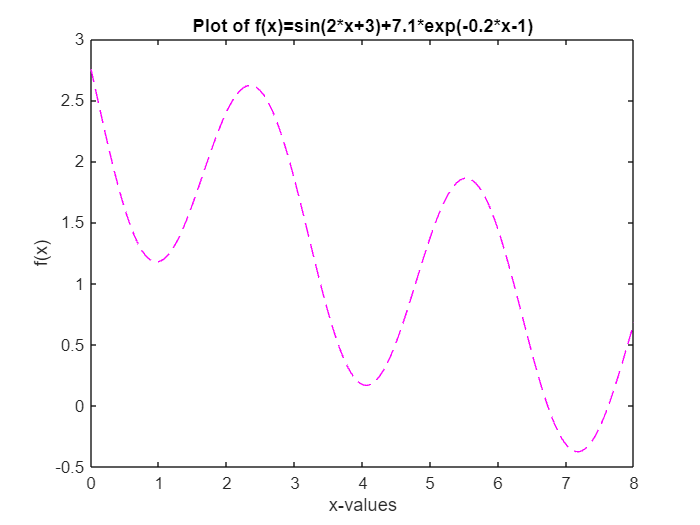

figure
plot(x,w,'m--')
xlabel('x-values')
ylabel('f(x)')
title('Plot of f(x)=sin(2*x+3)+7.1*exp(-0.2*x-1)')

## 5. Dealing with more complicated function relationships

Sometimes you need to multiply/divide several functions together and to do this for a large number of values involves coding with loops. However, MATLAB has a short cut which is often very useful and ensures the code is simple and readable.

In essence if we want to calculate a product such as $\textrm{xy}$ for a number of different values, [x1,x2,x3,...], [y1,y2,y3,...], that is we want [x1y1, x2y2, x3y3, ...] then MATLAB facilitates this with a 'dot' preceeding the desired operation.  Look at the simple example here.

disp('BELOW is SECTION 5')

BELOW is SECTION 5


x=[1 3 5 6]

x =      1     3     5     6


y=[-1 4 6 1]

y =     -1     4     6     1


w=x.*y     %% so w = [1*(-1)  3*4   5*6   6*1]

w =     -1    12    30     6


z=x./y     %% so z = [1/(-1)  3/4   5/6   6/1]

z =    -1.0000    0.7500    0.8333    6.0000


Next lets do a more interesting example and create the plot: 


$$f\left(x\right)=\frac{\textrm{xsin}\left(2x+3\right)}{e^{-0\ldotp 2x-1} }$$


Notice the placing of 'the dot' in line 41 before the relevant multiply or divide operator.Try changing the choice of the x values and indeed  the definition of w to gain more confidence with this.

x = linspace(-2,2,200)

x =    -2.0000   -1.9799   -1.9598   -1.9397   -1.9196   -1.8995   -1.8794   -1.8593   -1.8392   -1.8191   -1.7990   -1.7789   -1.7588   -1.7387   -1.7186   -1.6985   -1.6784   -1.6583   -1.6382   -1.6181   -1.5980   -1.5779   -1.5578   -1.5377   -1.5176   -1.4975   -1.4774   -1.4573   -1.4372   -1.4171   -1.3970   -1.3769   -1.3568   -1.3367   -1.3166   -1.2965   -1.2764   -1.2563   -1.2362   -1.2161   -1.1960   -1.1759   -1.1558   -1.1357   -1.1156   -1.0955   -1.0754   -1.0553   -1.0352   -1.0151


w = x.*sin(2*x+3)./exp(-0.2*x-1)

w =     3.0665    2.9668    2.8631    2.7557    2.6449    2.5308    2.4137    2.2940    2.1718    2.0474    1.9211    1.7933    1.6640    1.5337    1.4026    1.2710    1.1391    1.0072    0.8757    0.7446    0.6145    0.4854    0.3576    0.2314    0.1071   -0.0152   -0.1351   -0.2525   -0.3672   -0.4789   -0.5875   -0.6927   -0.7944   -0.8923   -0.9864   -1.0765   -1.1624   -1.2441   -1.3213   -1.3940   -1.4621   -1.5255   -1.5841   -1.6379   -1.6868   -1.7309   -1.7700   -1.8041   -1.8334   -1.8577


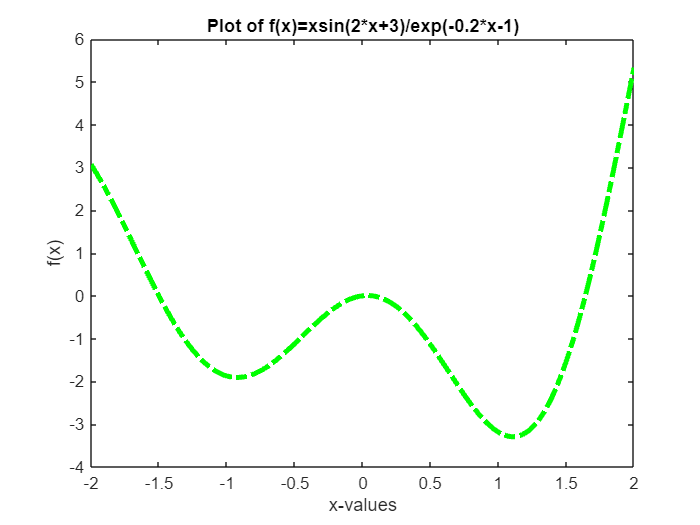

figure
plot(x,w,'g-.','linewidth',3)
xlabel('x-values')
ylabel('f(x)')
title('Plot of f(x)=xsin(2*x+3)/exp(-0.2*x-1)')

## 6. Overlaying plots of several curves using hold on

Often we want to overlay numerous line plots on the same figure and it is clumsy to write this in a single line or plot statement. A simple way to do this is to use ***hold on*** and ***hold off***. 

- ***Hold on*** means that each plot statement adds another item to the existing plot so you can accumulate line plots.

- ***Hold off*** means that using the plot statement will first wipe the figure clean and then plot anew.

The example below demonstrates by overlaying line plots for three different functions computed over different domains.

disp('BELOW is SECTION 6')

BELOW is SECTION 6


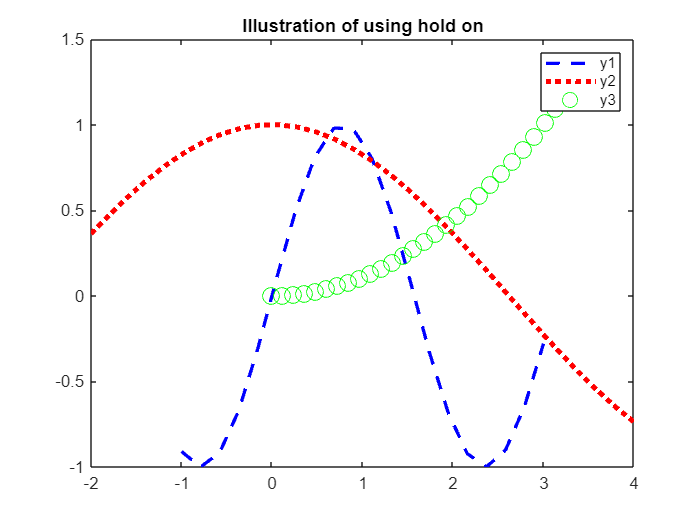

figure
x1 =linspace(-1,3,20);  % domain for plot 1
x2 = linspace(-2,4,30);   % domain for plot 2
x3 = linspace(0,3.5,30);   % domain for plot 3
y1=sin(2*x1);
y2 = cos(0.6*x2);
y3 = (x3/3).^2;
plot(x1,y1,'b--','linewidth',2)
hold on
plot(x2,y2,'r:','linewidth',3)
plot(x3,y3,'go','markersize',10)
legend('y1','y2','y3')
title('Illustration of using hold on')
hold off

**Remark**: Advised to put hold off at the end or future plot statements may add on to the same figure.